clc;clear;close all;
load Traininginfo.mat %load properties into the model
load Testinginfo.mat
en=fitcensemble(Traininginfo, 'state') %creates an Ensemble classification model

en =   ClassificationEnsemble
           PredictorNames: {'h vs. uh'  'TBint'}
             ResponseName: 'state'
    CategoricalPredictors: []
               ClassNames: {'N'  'T'}
           ScoreTransform: 'none'
          NumObservations: 50
               NumTrained: 100
                   Method: 'LogitBoost'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: [100×1 double]
       FitInfoDescription: {2×1 cell}


  Properties, Methods


prediction=predict(en, Testinginfo);
right=prediction==Testinginfo.state;
accuracy=sum(right)/numel(right) %determines the accuracy of the model

accuracy = 0.4800

percentacc=accuracy*100

percentacc = 48

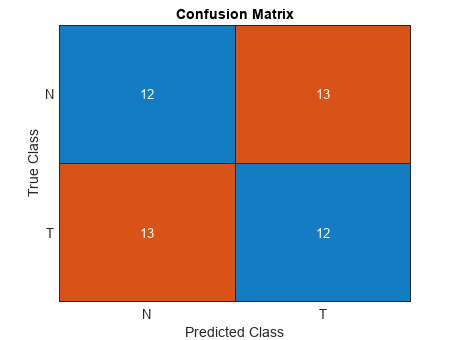


sinfo=Testinginfo.state; %displays the confusion chart
sinfo=cellstr(sinfo);
confusionchart(sinfo,prediction)
title("Confusion Matrix")